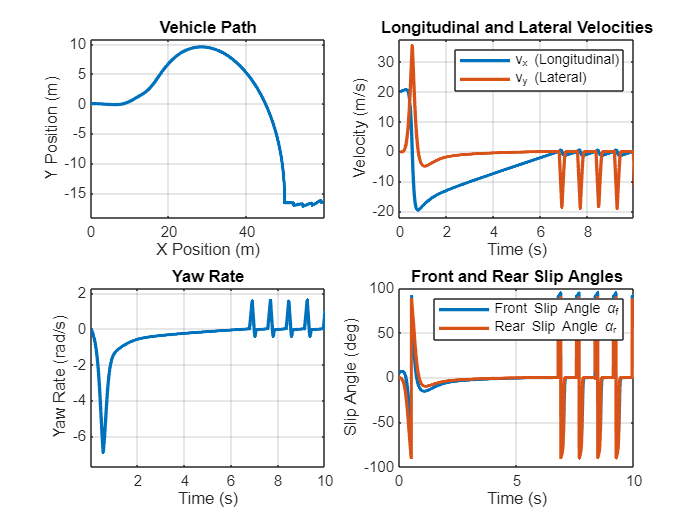

% Dynamic Bicycle Model Simulation in Vehicle Dynamics
clear all; close all; clc;

% Vehicle Parameters
m = 1500;              % Vehicle mass (kg)
Iz = 3000;             % Moment of inertia about z-axis (kg*m^2)
lf = 1.2;              % Distance from CG to front axle (m)
lr = 1.6;              % Distance from CG to rear axle (m)
Cf = 80000;            % Front cornering stiffness (N/rad)
Cr = 80000;            % Rear cornering stiffness (N/rad)
delta = deg2rad(5);    % Steering angle (rad) [constant for simplicity]
Fx = 4000;             % Longitudinal force (N) [constant for simplicity]

% Simulation Parameters
T = 10;                % Total simulation time (s)
dt = 0.01;             % Time step (s)
time = 0:dt:T;         % Time vector

% Initial Conditions [vx, vy, yaw_rate, x, y, yaw_angle]
initial_conditions = [20; 0; 0; 0; 0; 0]; % vx = 20 m/s (initial forward velocity)

% Solve the dynamic model using ode45
[t, state] = ode45(@(t, state) dynamic_bicycle_model(t, state, m, Iz, lf, lr, Cf, Cr, delta, Fx), time, initial_conditions);

% Extract states
vx = state(:, 1);       % Longitudinal velocity
vy = state(:, 2);       % Lateral velocity
yaw_rate = state(:, 3); % Yaw rate
x = state(:, 4);        % X position
y = state(:, 5);        % Y position
yaw = state(:, 6);      % Yaw angle (theta)

% Plot Results
figure;

% Vehicle Path
subplot(2,2,1);
plot(x, y, 'LineWidth', 2);
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Vehicle Path');
grid on;

% Velocities
subplot(2,2,2);
plot(t, vx, 'LineWidth', 2); hold on;
plot(t, vy, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Longitudinal and Lateral Velocities');
legend('v_x (Longitudinal)', 'v_y (Lateral)');
grid on;

% Yaw Rate
subplot(2,2,3);
plot(t, yaw_rate, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Yaw Rate (rad/s)');
title('Yaw Rate');
grid on;

% Slip Angles
alpha_f = delta - atan((vy + lf * yaw_rate) ./ vx);
alpha_r = -atan((vy - lr * yaw_rate) ./ vx);
subplot(2,2,4);
plot(t, rad2deg(alpha_f), 'LineWidth', 2); hold on;
plot(t, rad2deg(alpha_r), 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Slip Angle (deg)');
title('Front and Rear Slip Angles');
legend('Front Slip Angle \alpha_f', 'Rear Slip Angle \alpha_r');
grid on;


% Function: Dynamic Bicycle Model Equations
function dstate = dynamic_bicycle_model(t, state, m, Iz, lf, lr, Cf, Cr, delta, Fx)
    % State Variables
    vx = state(1);       % Longitudinal velocity
    vy = state(2);       % Lateral velocity
    yaw_rate = state(3); % Yaw rate
    x = state(4);        % X position
    y = state(5);        % Y position
    yaw = state(6);      % Yaw angle
    
    % Slip Angles
    alpha_f = delta - atan((vy + lf * yaw_rate) / vx);
    alpha_r = -atan((vy - lr * yaw_rate) / vx);
    
    % Lateral Forces (Linear tire model)
    Fyf = -Cf * alpha_f;
    Fyr = -Cr * alpha_r;
    
    % Equations of Motion
    vx_dot = (1 / m) * (Fx - Fyf * sin(delta)) + vy * yaw_rate; % Longitudinal acceleration
    vy_dot = (1 / m) * (Fyf * cos(delta) + Fyr) - vx * yaw_rate; % Lateral acceleration
    yaw_rate_dot = (1 / Iz) * (Fyf * cos(delta) * lf - Fyr * lr); % Yaw acceleration
    
    % Vehicle Position Update
    x_dot = vx * cos(yaw) - vy * sin(yaw);
    y_dot = vx * sin(yaw) + vy * cos(yaw);
    yaw_dot = yaw_rate;
    
    % Return Derivatives
    dstate = [vx_dot; vy_dot; yaw_rate_dot; x_dot; y_dot; yaw_dot];
end
